# Experiment A

clear; clc; close all;
rx = sdrrx('Pluto');
rx.CenterFrequency = 2.44e9;
rx.BasebandSampleRate = 25e6;
rx.SamplesPerFrame = 65536;
rx.OutputDataType = 'double';
rx.GainSource = 'Manual';
rx.Gain = 15;
Fs = rx.BasebandSampleRate;
sa = spectrumAnalyzer('SampleRate',Fs, ...
    'SpectrumType','Power density', ...
    'FrequencySpan','Full');
disp('Observe OFF and ON. Stop with Ctrl+C.');

Observe OFF and ON. Stop with Ctrl+C.


while true
    x = rx();
    x = x - mean(x); % suppress receiver DC artifact
    sa(x);
end

## Establishing connection to hardware. This process can take several seconds.


% After stopping, run: release(rx); release(sa);

% Question 1: 2.4375 - 2.4425 GHz. The peak at 0 Hz represents the DC
% artifact. No observable constant change within the spectrum


## Experiment B

clear; clc; close all;
rx = sdrrx('Pluto');
fc = 2.412e9; Fs = 25e6; N = 65536; nFrames = 30;
rx.CenterFrequency = fc;
rx.BasebandSampleRate = Fs;
rx.SamplesPerFrame = N;
rx.OutputDataType = 'double';
rx.GainSource = 'Manual'; rx.Gain = 15;
input('Controller OFF: press Enter to record ');
off = complex(zeros(N*nFrames,1));
for k=1:nFrames
    off((k-1)*N+(1:N)) = rx();
end

## Establishing connection to hardware. This process can take several seconds.


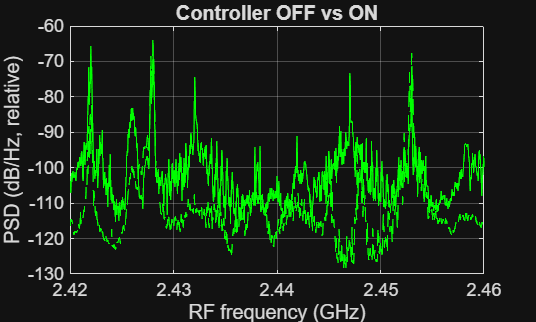

input('Controller ON, operate steering: press Enter ');
on = complex(zeros(N*nFrames,1));
for k=1:nFrames
    on((k-1)*N+(1:N)) = rx();
end
release(rx);
off = off-mean(off); on = on-mean(on);
nfft=2048; w=hann(nfft);
[po,f] = pwelch(off,w,nfft/2,nfft,Fs,'centered');
[pn,~] = pwelch(on,w,nfft/2,nfft,Fs,'centered');
figure;
plot((fc+f)/1e9,10*log10(po+eps),'g--'); hold on;
plot((fc+f)/1e9,10*log10(pn+eps),'g-');
xlabel('RF frequency (GHz)'); ylabel('PSD (dB/Hz, relative)');
legend('OFF','ON'); grid on; title('Controller OFF vs ON');

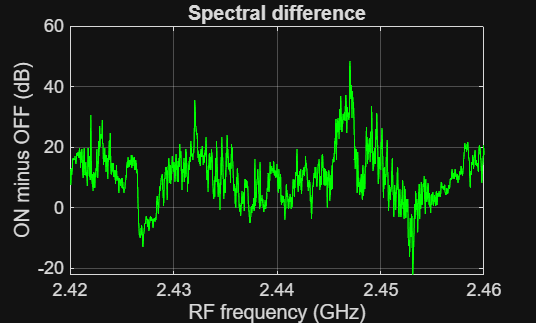

figure;
plot((fc+f)/1e9,10*log10((pn+eps)./(po+eps)),'g');
xlabel('RF frequency (GHz)'); ylabel('ON minus OFF (dB)');
grid on; title('Spectral difference');


% Question 1: 


## Experiment C

clear; clc; close all;
rx = sdrrx('Pluto');
Fs = 25e6; N = 16384;
rx.BasebandSampleRate = Fs;
rx.SamplesPerFrame = N;
rx.OutputDataType = 'double';
rx.GainSource = 'Manual'; rx.Gain = 15;
freq = 2.402e9:2e6:2.482e9;
nRepeat = 3; framesPerCenter = 12;
Poff = zeros(numel(freq),nRepeat);
Pon = zeros(numel(freq),nRepeat);

for rep=1:nRepeat
    input(sprintf('Round %d: controller OFF. Enter ',rep));
    for k=1:numel(freq)
        rx.CenterFrequency=freq(k);
        rx(); rx(); % discard initial frames after retuning
        pp=zeros(framesPerCenter,1);
        for j=1:framesPerCenter
            x=rx(); x=x-mean(x);
            pp(j)=mean(abs(x).^2);
        end
        Poff(k,rep)=max(pp);
    end

    input(sprintf('Round %d: controller ON; operate steering. Enter ',rep));
    for k=1:numel(freq)
    rx.CenterFrequency=freq(k);
    rx(); rx();
    pp=zeros(framesPerCenter,1);
        for j=1:framesPerCenter
        x=rx(); x=x-mean(x);
        pp(j)=mean(abs(x).^2);
        end
    Pon(k,rep)=max(pp);
    end
end

## Establishing connection to hardware. This process can take several seconds.


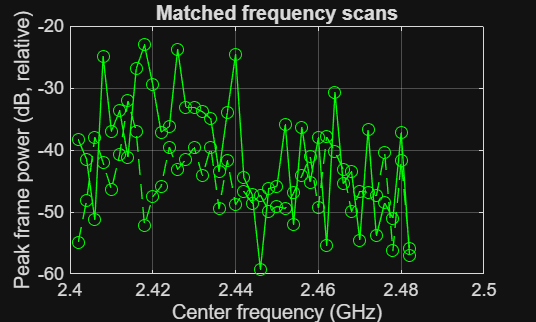

release(rx);

offdB=10*log10(Poff+eps);
ondB=10*log10(Pon+eps);
delta=ondB-offdB;

figure;
plot(freq/1e9,mean(offdB,2),'g--o'); hold on;
plot(freq/1e9,mean(ondB,2),'g-o');
xlabel('Center frequency (GHz)');
ylabel('Peak frame power (dB, relative)');
legend('OFF','ON'); grid on; title('Matched frequency scans');

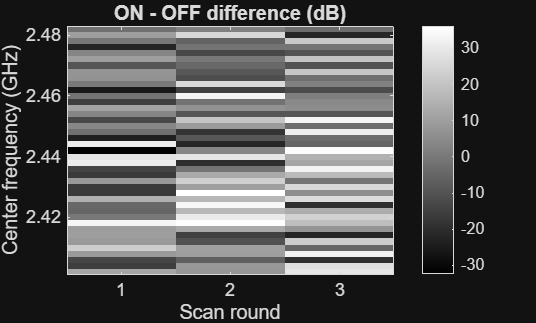


figure;
imagesc(1:nRepeat,freq/1e9,delta);
axis xy; colormap(gray); colorbar;
xlabel('Scan round'); ylabel('Center frequency (GHz)');
title('ON - OFF difference (dB)');

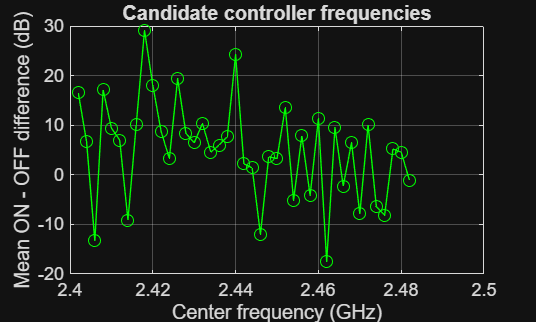

figure;
plot(freq/1e9,mean(delta,2),'g-o');
xlabel('Center frequency (GHz)');
ylabel('Mean ON - OFF difference (dB)');
grid on; title('Candidate controller frequencies');

[~,ix]=sort(mean(delta,2),'descend');
disp('Top candidate center frequencies (GHz):');

Top candidate center frequencies (GHz):


disp(freq(ix(1:min(8,end)))'/1e9);

    2.4180
    2.4400
    2.4260
    2.4200
    2.4080
    2.4020
    2.4520
    2.4600



save('RC_scan_OFF_ON.mat','freq','Poff','Pon','delta','Fs');


## Experiment D

clear; clc; close all;
rx = sdrrx('Pluto');
fc = 2.412e9; % replace with your candidate center
Fs = 20e6; N = 20000; nFrames = 100;
rx.CenterFrequency = fc;
rx.BasebandSampleRate = Fs;
rx.SamplesPerFrame = N;
rx.OutputDataType = 'double';
rx.GainSource = 'Manual'; rx.Gain = 0;
input('Operate controller, then press Enter ');
IQ = complex(zeros(N*nFrames,1));
for k=1:nFrames
    IQ((k-1)*N+(1:N)) = rx();
end

## Establishing connection to hardware. This process can take several seconds.


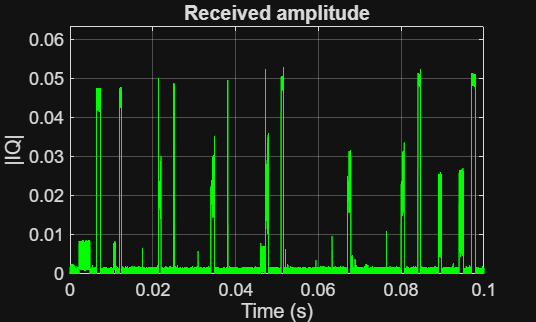

release(rx);
IQ = IQ - mean(IQ);
save('RC_IQ.mat','IQ','Fs','fc','-v7.3');

t = (0:numel(IQ)-1)/Fs;
figure;
plot(t,abs(IQ),'g');
xlabel('Time (s)'); ylabel('|IQ|');
title('Received amplitude'); grid on;
ylim([0 1.2*max(abs(IQ))]);

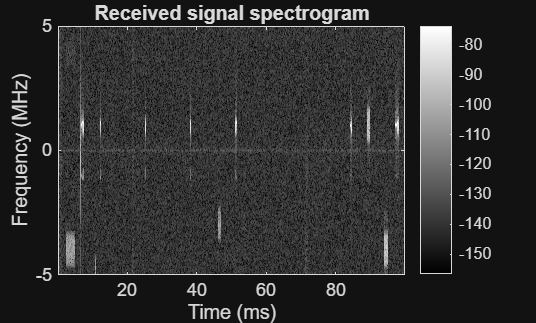


figure;
spectrogram(IQ,hann(512),384,1024,Fs,'centered','yaxis');
ylim([-5 5]);
title('Received signal spectrogram');
colormap(gray); colorbar;

## Experiment E


clear; clc; close all;

% Pluto receiver configuration
rx = sdrrx('Pluto');

fc = 2.413e9;
Fs = 20e6;
N = 16384;

rx.CenterFrequency = fc;
rx.BasebandSampleRate = Fs;
rx.SamplesPerFrame = N;
rx.OutputDataType = 'double';
rx.GainSource = 'Manual';
rx.Gain = 15;

% Recording configuration
recordTime = 1;
nFrames = ceil(recordTime*Fs/N);

% Controller states
commands = {'neutral', ...
            'forward', ...
            'reverse', ...
            'left', ...
            'right', ...
            'forward_left', ...
            'forward_right'};

fprintf('Starting RC controller characterization\n');

Starting RC controller characterization



for k = 1:length(commands)

    fprintf('\nPrepare controller state: %s\n',commands{k});

    input('Press Enter when ready to record...');

    IQ = complex(zeros(N*nFrames,1));

    for j = 1:nFrames
        idx = (j-1)*N+(1:N);
        IQ(idx) = rx();
    end

    % Remove receiver DC offset
    IQ = IQ - mean(IQ);

    % Save individual recording
    filename = ['RC_' commands{k} '.mat'];

    save(filename,'IQ','Fs','fc','recordTime','-v7.3');

    fprintf('Saved %s\n',filename);

end


Prepare controller state: neutral


## Establishing connection to hardware. This process can take several seconds.


Saved RC_neutral.mat



Prepare controller state: forward


Saved RC_forward.mat



Prepare controller state: reverse


Saved RC_reverse.mat



Prepare controller state: left


Saved RC_left.mat



Prepare controller state: right


Saved RC_right.mat



Prepare controller state: forward_left


Saved RC_forward_left.mat



Prepare controller state: forward_right


Saved RC_forward_right.mat



release(rx);

disp('All recordings completed.');

All recordings completed.


## EXPERIMENT F: RC SIGNAL CHARACTERIZATION


Analyzing: neutral


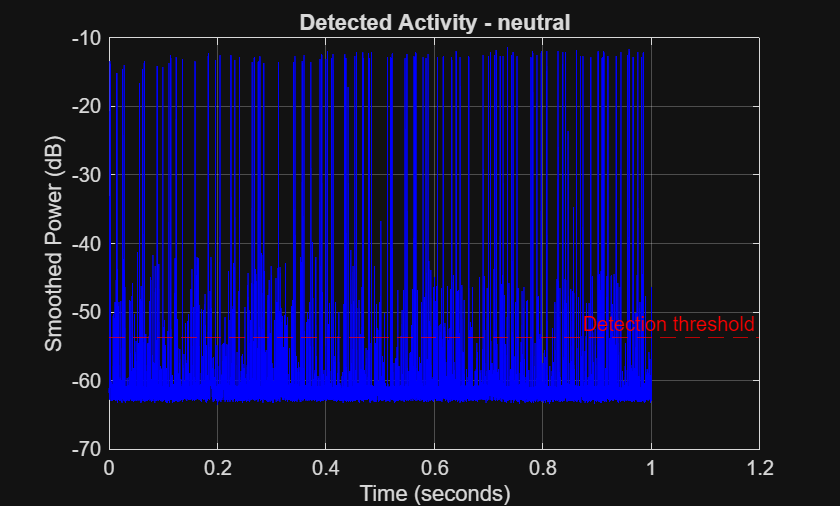

Detected bursts: 342


Average duration: 0.000272 seconds


Maximum duration: 0.001545 seconds


Average interval: 0.002927 seconds



Analyzing: forward


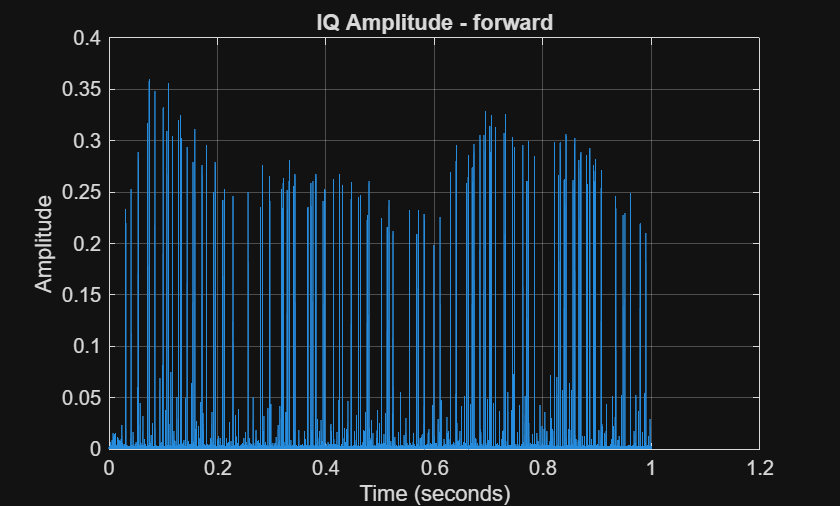

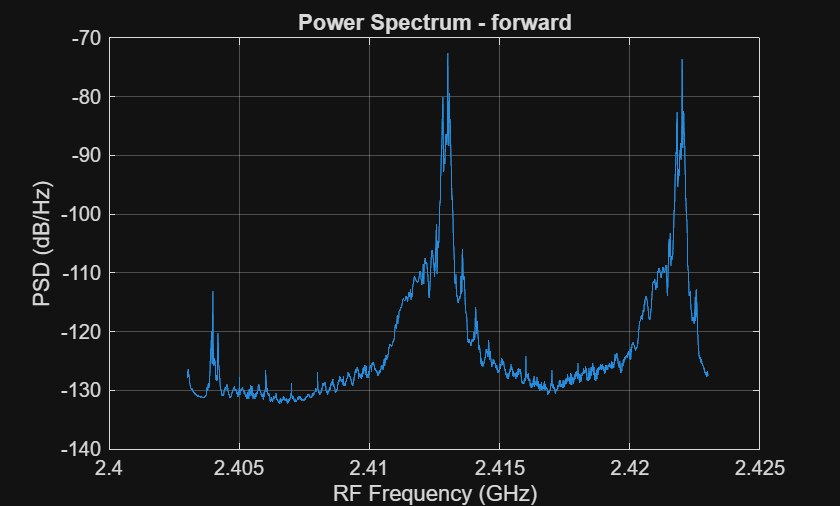

Out of memory.

Error in pspectrogram>displayspectrogram (line 192)
signalwavelet.internal.convenienceplot.plotTFR(t,f, 10*log10(abs(Pxx)+eps("double")),plotOpts);
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in pspectrogram (line 100)
        displayspectrogram(t,f,P,isnormfreq,options.faxi

commands = {'neutral', ...
            'forward', ...
            'reverse', ...
            'left', ...
            'right', ...
            'forward_left', ...
            'forward_right'};

numCommands = length(commands);

% Analysis parameters
smoothTime = 10e-6;       % RMS smoothing window
mergeGapTime = 100e-6;    % Merge very short gaps
thresholdDB = 8;          % Threshold above estimated noise floor

results = cell(numCommands,1);

for k = 1:numCommands

    filename = ['RC_' commands{k} '.mat'];

    if ~isfile(filename)
        warning('Missing file: %s',filename);
        continue;
    end

    %% LOAD RECORDING

    S = load(filename);

    IQ = S.IQ(:);
    Fs = S.Fs;
    fc = S.fc;

    t = (0:length(IQ)-1)/Fs;

    fprintf('\nAnalyzing: %s\n',commands{k});

    %% 1. AMPLITUDE ANALYSIS

    figure('Name',[commands{k} ' - Amplitude']);

    plot(t,abs(IQ));
    xlabel('Time (seconds)');
    ylabel('Amplitude');
    title(['IQ Amplitude - ' commands{k}]);
    grid on;

    %% 2. POWER SPECTRAL DENSITY

    nfft = 4096;
    window = hann(nfft);

    [Pxx,f] = pwelch(IQ,window,nfft/2,...
                     nfft,Fs,'centered');

    figure('Name',[commands{k} ' - Spectrum']);

    plot((fc+f)/1e9,10*log10(Pxx+eps));

    xlabel('RF Frequency (GHz)');
    ylabel('PSD (dB/Hz)');
    title(['Power Spectrum - ' commands{k}]);
    grid on;

    %% 3. SPECTROGRAM

    figure('Name',[commands{k} ' - Spectrogram']);

    spectrogram(IQ,hann(1024),768,...
                2048,Fs,'centered','yaxis');

    title(['Spectrogram - ' commands{k}]);
    colorbar;

    %% 4. ESTIMATE TRANSMISSION ACTIVITY

    % Calculate smoothed signal power
    smoothSamples = max(1,round(smoothTime*Fs));

    powerSignal = movmean(abs(IQ).^2,smoothSamples);

    powerDB = 10*log10(powerSignal+eps);

    % Estimate background level
    noiseFloor = median(powerDB);

    % Detect periods above threshold
    threshold = noiseFloor + thresholdDB;

    active = powerDB > threshold;

    %% 5. MERGE SHORT GAPS

    % Join detections separated by very short gaps
    maxGap = round(mergeGapTime*Fs);

    edges = diff([false; active; false]);

    starts = find(edges == 1);
    stops = find(edges == -1)-1;

    if length(starts) > 1

        newStarts = starts(1);
        newStops = [];

        for j = 1:length(starts)-1

            if starts(j+1)-stops(j)-1 <= maxGap
                continue;
            else
                newStops(end+1,1) = stops(j);
                newStarts(end+1,1) = starts(j+1);
            end

        end

        newStops(end+1,1) = stops(end);

        starts = newStarts;
        stops = newStops;

    end

    %% 6. CALCULATE BURST STATISTICS

    burstCount = length(starts);

    burstDuration = (stops-starts+1)/Fs;

    if burstCount > 1
        burstIntervals = diff(starts)/Fs;
    else
        burstIntervals = [];
    end

    if burstCount > 0

        avgDuration = mean(burstDuration);
        maxDuration = max(burstDuration);

    else

        avgDuration = NaN;
        maxDuration = NaN;

    end

    if ~isempty(burstIntervals)
        avgInterval = mean(burstIntervals);
    else
        avgInterval = NaN;
    end

    %% 7. PLOT DETECTED BURSTS

    figure('Name',[commands{k} ' - Burst Detection']);

    plot(t,powerDB,'b');
    hold on;

    yline(threshold,'r--','Detection threshold');

    xlabel('Time (seconds)');
    ylabel('Smoothed Power (dB)');
    title(['Detected Activity - ' commands{k}]);

    grid on;

    %% SAVE RESULTS

    results{k} = struct( ...
        'Command',commands{k}, ...
        'BurstCount',burstCount, ...
        'AverageDuration',avgDuration, ...
        'MaximumDuration',maxDuration, ...
        'AverageInterval',avgInterval, ...
        'NoiseFloor',noiseFloor);

    fprintf('Detected bursts: %d\n',burstCount);
    fprintf('Average duration: %.6f seconds\n',avgDuration);
    fprintf('Maximum duration: %.6f seconds\n',maxDuration);
    fprintf('Average interval: %.6f seconds\n',avgInterval);

end


%% 8. SUMMARY TABLE

valid = ~cellfun(@isempty,results);

R = vertcat(results{valid});

Summary = struct2table(R);

disp(' ');
disp('EXPERIMENT F SUMMARY');
disp(Summary);

save('RC_Experiment_F_Results.mat','results','Summary');

disp('Experiment F completed.');
